ECoG_data_dir = "/home/linux-pc/gh/CRCNS/src/motor_cortex/data/data/Ipsilateral/2018-04-29_(S1)/ECoG.mat"

ECoG_data_dir = "/home/linux-pc/gh/CRCNS/src/motor_cortex/data/data/Ipsilateral/2018-04-29_(S1)/ECoG.mat"

Motion_data_dir = "/home/linux-pc/gh/CRCNS/src/motor_cortex/data/data/Ipsilateral/2018-04-29_(S1)/Motion.mat"

Motion_data_dir = "/home/linux-pc/gh/CRCNS/src/motor_cortex/data/data/Ipsilateral/2018-04-29_(S1)/Motion.mat"


ECoG_data_predictions_dir = "/home/linux-pc/gh/CRCNS/src/motor_cortex/data/data/Ipsilateral/2018-04-29_(S1)/ecog_predictions.mat"

ECoG_data_predictions_dir = "/home/linux-pc/gh/CRCNS/src/motor_cortex/data/data/Ipsilateral/2018-04-29_(S1)/ecog_predictions.mat"

ECoG_data = load(ECoG_data_dir);
Motion_data = load(Motion_data_dir);
ECoG_predictions = load(ECoG_data_predictions_dir);

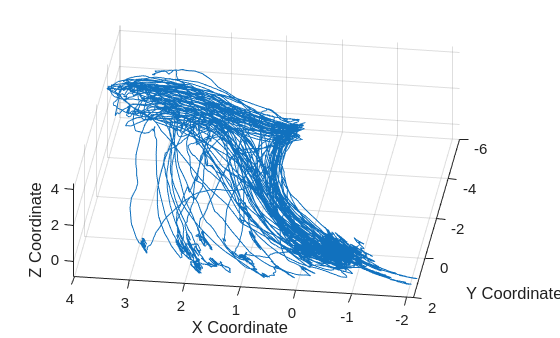

figure;
title("Ipsilateral Motion Data, Session 1, Right Wrist");
plot3(Motion_data.Right_Wrist(:,1), Motion_data.Right_Wrist(:,2), Motion_data.Right_Wrist(:,3))
xlabel("X Coordinate");
ylabel("Y Coordinate");
zlabel("Z Coordinate");
grid("on")

view([-89.72 90.00])
view([187.78 60.00])

pred_X = ECoG_predictions.predictions(:,1);
pred_Y = ECoG_predictions.predictions(:,2);
pred_Z = ECoG_predictions.predictions(:,3);

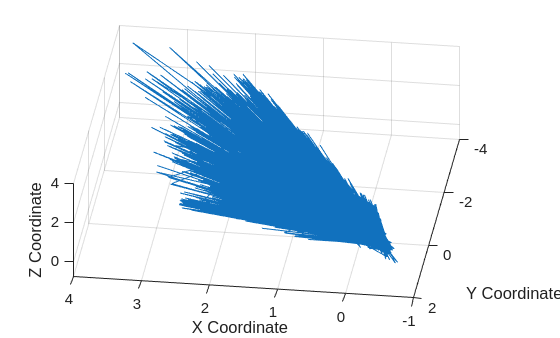

% Plotting the predictioned values of motion
figure;
title("Ipsilateral Motion Data Predictions, Session 1, Right Wrist");
plot3(pred_X, pred_Y, pred_Z)
xlabel("X Coordinate");
ylabel("Y Coordinate");
zlabel("Z Coordinate");
grid("on")

view([-89.72 90.00])

view([187.78 60.00])

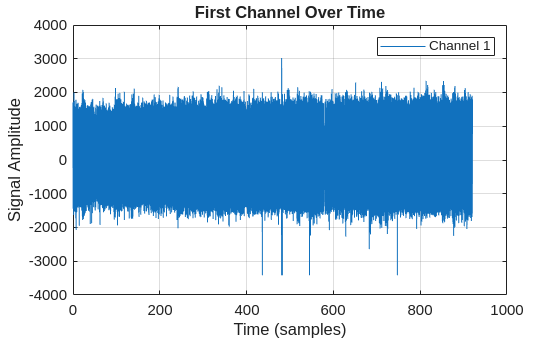


% Assume your matrix is named 'data'
% Plot first 3 channels
time = ECoG_data.ECoG_time;
figure;
plot(time, ECoG_data.ECoG(:, (1:1)));
legend('Channel 1');
xlabel('Time (samples)');
ylabel('Signal Amplitude');
title('First Channel Over Time');
grid on;